# Práctica 10.

#### Ejercicio 1.

Ver directamente en el archivo `p10ej1.mph` de COMSOL. Contiene todo lo que se pide en el apartado, que es:

- Norma $L^{2}(\Omega)$ del error de aproximación de la solución.

- Norma $L^{2}(\Omega)$ del error de aproximación del gradiente.

- Norma $H^{1}(\Omega)$ del error de aproximación de la solución.

#### Ejercicio 2.

a) Sabemos de la Práctica 8 que la formulación débil del problema es $\int_{\Omega}\nabla u\cdot\nabla vd\Omega=\int_{\Omega}\delta(r) vd\Omega=v(0)$ por las propiedades de la función $\delta$. Si tomamos la función $u=-\frac{1}{2\pi}\log(r)$ podemos ver que $\nabla u=\frac{-1}{2\pi r}$ por tanto, $\int_{\Omega}\nabla u\cdot\nabla vd\Omega=v(0)\iff\int_{\Omega}\frac{-1}{2\pi r}\cdot\frac{\partial v}{\partial r}drd\theta=v(0)$, que implica $\int_{r=0}^{r_{ext}}\frac{-1}{r}\cdot\frac{\partial v}{\partial r}dr=v(0)$, con lo cual no tenemos más que aplicar las condiciones de contorno para $v$.

b) Abrimos el archivo `p10ej2_MatLab.m` con el *pdetool*.

pdetool;

Con el mallado homogéneo resulta, representando malla, solución y error (`abs(u+1./(2.*pi)*log(sqrt(x.^2+y.^2)))`):

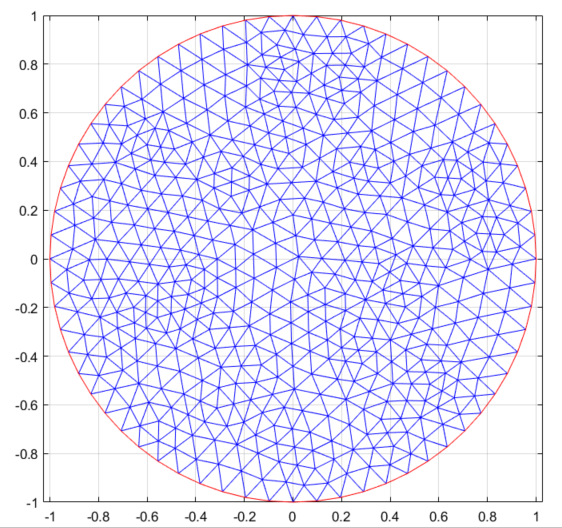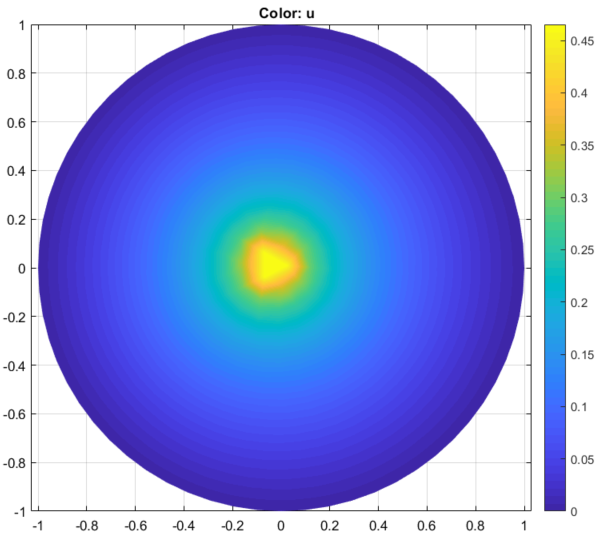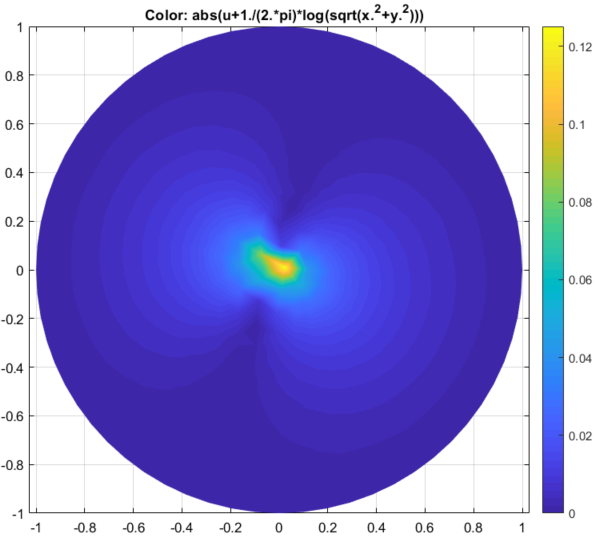

La norma $L^{2}(\Omega)$ del error de aproximación de la solución para la malla homogénea es:

error_u=u-(1-p(1,:)'.^2-p(2,:)'.^2)/4;
normal2(error_u,t,p,1)

ans = 0.1070

El mallado adaptativo arroja una solución:

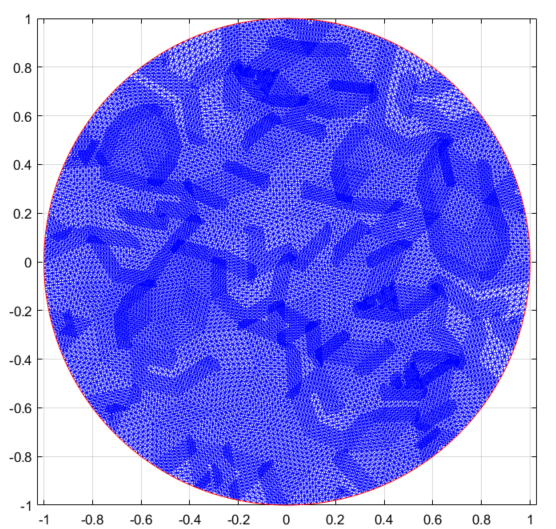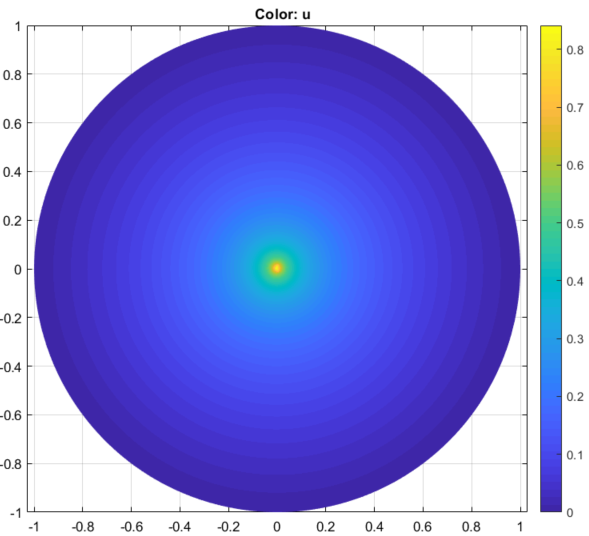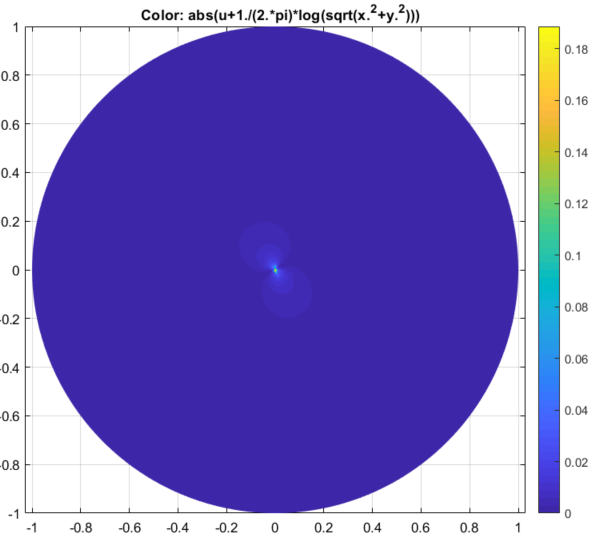

La norma $L^{2}(\Omega)$ del error de aproximación de la solución para la malla adaptada es:

error_uad=uad-(1-pad(1,:)'.^2-pad(2,:)'.^2)/4;
normal2(error_uad,t,pad,1)

ans = 0.1070

c) Repetimos el trabajo con COMSOL. De nuevo, en este caso vamos a realizar todo el trabajo en el propio archivo `p10ej2_COMSOL.mph`.

## Anexo.

function z=normal2(u,t,p,opint)
% Función que calcula la norma L^2 de una función u definida en cada nodo
% de la malla sobre el dominio definido por la malla t en el formato de
% pdetool.
% La función u debe estar definida sobre los nodos de la malla.
% La matriz p representa las coordenadas de los nodos.
% La matriz t representa la información sobre los elementos: sus vértices y
% el dominio al que pertenecen.
% opint es la opción de integración.
% opint==1, si se utiliza la aproximación numérica del valor medio
% opint==2, si se calcula la integral exacta sobre cada elemento
% Si el número de argumentos es 3, se entiende que opint=1

if nargin==3
    opint=1;
end
if opint==2
    syms x y
    PRef=[1-x-y, x, y];
    integrando=PRef'*PRef;
    Integ1=int(integrando, 'y', 0, 1-x);
    Integ2=int(Integ1,'x',0,1);
    IntegralRef=eval(Integ2);
end
nel=length(t(1,:));
z=0;
for k=1:nel
    uk=u(t(1:3,k));
    Bk=[p(:,t(2,k))-p(:,t(1,k)), p(:,t(3,k))-p(:,t(1,k))];
    if opint==1
        areak=abs(det(Bk))*0.5;
        Integralk=sum(uk.^2)/3*areak;
    else
        Integralk=abs(det(Bk))*uk'*IntegralRef*uk;
    end
    z=z+Integralk;
end
z=sqrt(z);
end